
% Day 1: UAV vertical kinematics
clear;
clc;
close all;

% Simulation time from 0 to 4 seconds
dt = 0.01;
t = (0:dt:4)';

% Initial conditions and constant acceleration
z0 = 0;          % Initial altitude (m)
v0 = 0;          % Initial velocity (m/s)
a0 = 0.2;        % Acceleration (m/s^2)

% Calculate the motion
a = a0 * ones(size(t));
v = v0 + a0*t;
z = z0 + v0*t + 0.5*a0*t.^2;

% Check the result at 4 seconds
fprintf('Final velocity = %.2f m/s\n', v(end));

Final velocity = 0.80 m/s


fprintf('Final altitude = %.2f m\n', z(end));

Final altitude = 1.60 m


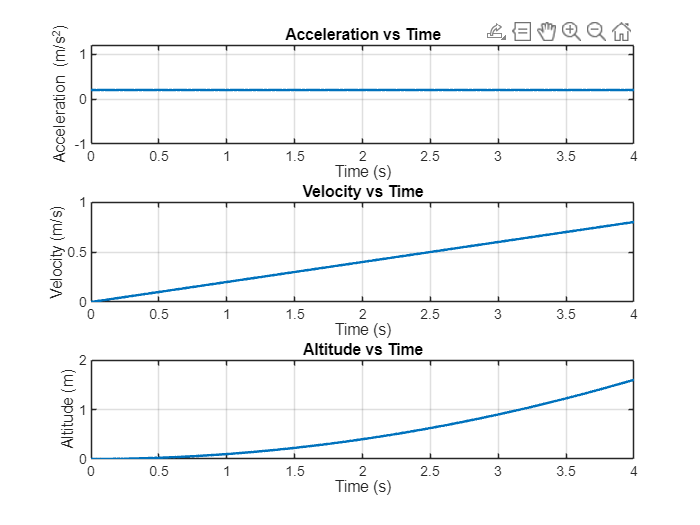


assert(abs(v(end) - 0.8) < 1e-10);
assert(abs(z(end) - 1.6) < 1e-10);

% Plot acceleration, velocity and altitude
figure('Name','Day 1 UAV Kinematics');

subplot(3,1,1);
plot(t,a,'LineWidth',1.5);
grid on;
title('Acceleration vs Time');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');

subplot(3,1,2);
plot(t,v,'LineWidth',1.5);
grid on;
title('Velocity vs Time');
xlabel('Time (s)');
ylabel('Velocity (m/s)');

subplot(3,1,3);
plot(t,z,'LineWidth',1.5);
grid on;
title('Altitude vs Time');
xlabel('Time (s)');
ylabel('Altitude (m)');